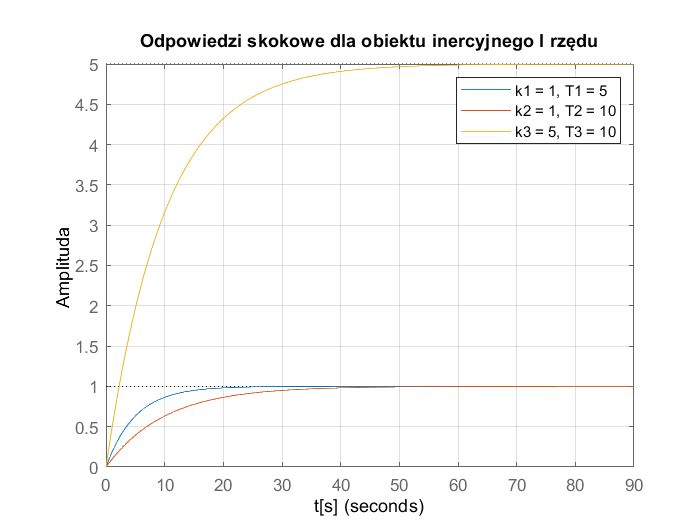

% obiekt inercyjny I rzędu
figure
hold on
step([0, 1], [5, 1]); 
step([0, 1], [10, 1]); 
step([0, 5], [10, 1]); 
title("Odpowiedzi skokowe dla obiektu inercyjnego I rzędu")
xlabel("t[s]")
ylabel("Amplituda")
legend(["k1 = 1, T1 = 5", "k2 = 1, T2 = 10", "k3 = 5, T3 = 10"])
grid on

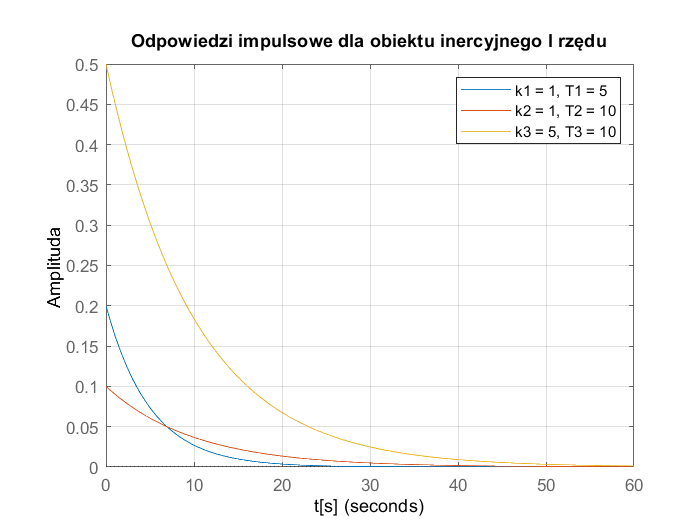


figure
hold on
impulse([0, 1], [5, 1]); 
impulse([0, 1], [10, 1]); 
impulse([0, 5], [10, 1]); 
title("Odpowiedzi impulsowe dla obiektu inercyjnego I rzędu")
xlabel("t[s]")
ylabel("Amplituda")
legend(["k1 = 1, T1 = 5", "k2 = 1, T2 = 10", "k3 = 5, T3 = 10"])
grid on

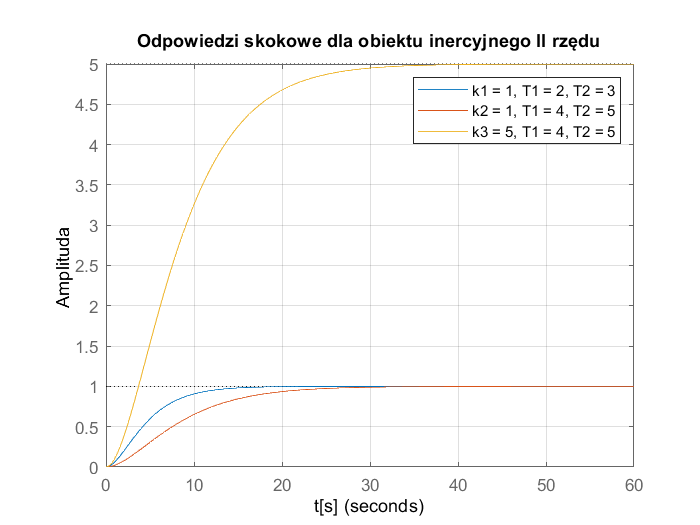

% obiekt inercyjny II rzędu
figure
hold on
step([0, 0, 1], [6, 5, 1]); 
step([0, 0, 1], [20, 9, 1]); 
step([0, 0, 5], [20, 9, 1]); 
title("Odpowiedzi skokowe dla obiektu inercyjnego II rzędu")
xlabel("t[s]")
ylabel("Amplituda")
legend(["k1 = 1, T1 = 2, T2 = 3", "k2 = 1, T1 = 4, T2 = 5", "k3 = 5, T1 = 4, T2 = 5"])
grid on

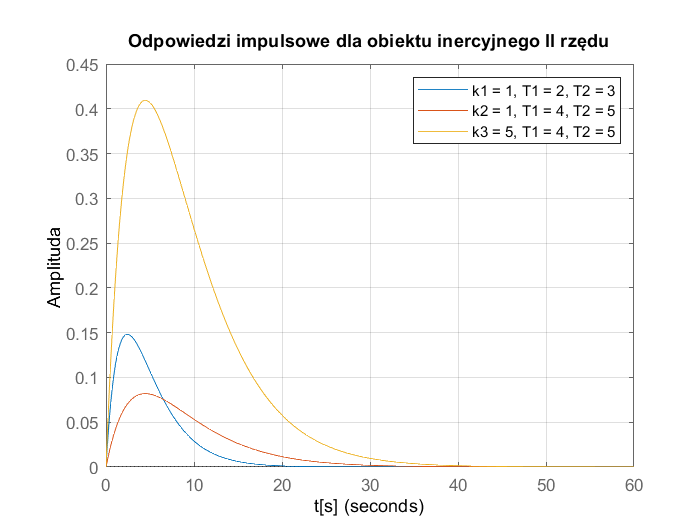


figure
hold on
impulse([0, 0, 1], [6, 5, 1]); 
impulse([0, 0, 1], [20, 9, 1]); 
impulse([0, 0, 5], [20, 9, 1]); 
title("Odpowiedzi impulsowe dla obiektu inercyjnego II rzędu")
xlabel("t[s]")
ylabel("Amplituda")
legend(["k1 = 1, T1 = 2, T2 = 3", "k2 = 1, T1 = 4, T2 = 5", "k3 = 5, T1 = 4, T2 = 5"]) 
grid on

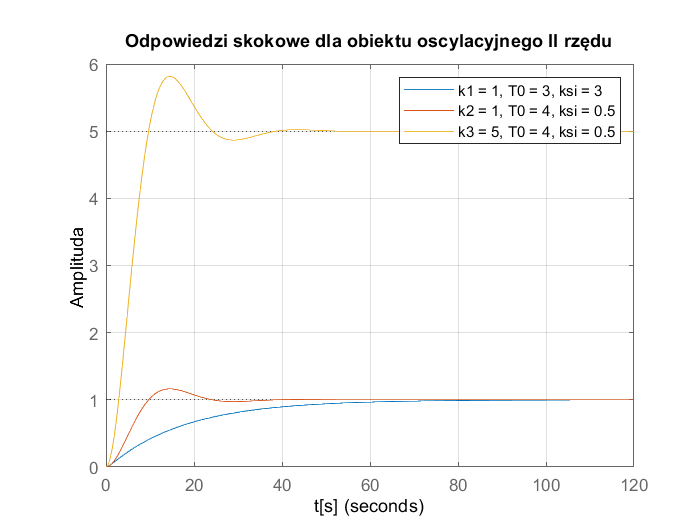

% obiekt oscylacyjny II rzędu
figure
hold on
step([0, 0, 1], [9, 18, 1]); 
step([0, 0, 1], [16, 4, 1]); 
step([0, 0, 5], [16, 4, 1]); 
title("Odpowiedzi skokowe dla obiektu oscylacyjnego II rzędu")
xlabel("t[s]")
ylabel("Amplituda")
legend(["k1 = 1, T0 = 3, ksi = 3", "k2 = 1, T0 = 4, ksi = 0.5", "k3 = 5, T0 = 4, ksi = 0.5"])
grid on

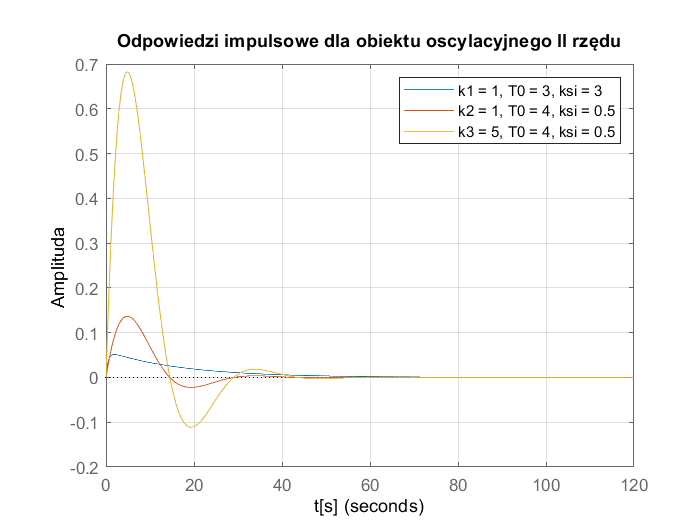


figure
hold on
impulse([0, 0, 1], [9, 18, 1]); 
impulse([0, 0, 1], [16, 4, 1]); 
impulse([0, 0, 5], [16, 4, 1]); 
title("Odpowiedzi impulsowe dla obiektu oscylacyjnego II rzędu")
xlabel("t[s]")
ylabel("Amplituda")
legend(["k1 = 1, T0 = 3, ksi = 3", "k2 = 1, T0 = 4, ksi = 0.5", "k3 = 5, T0 = 4, ksi = 0.5"])
grid on

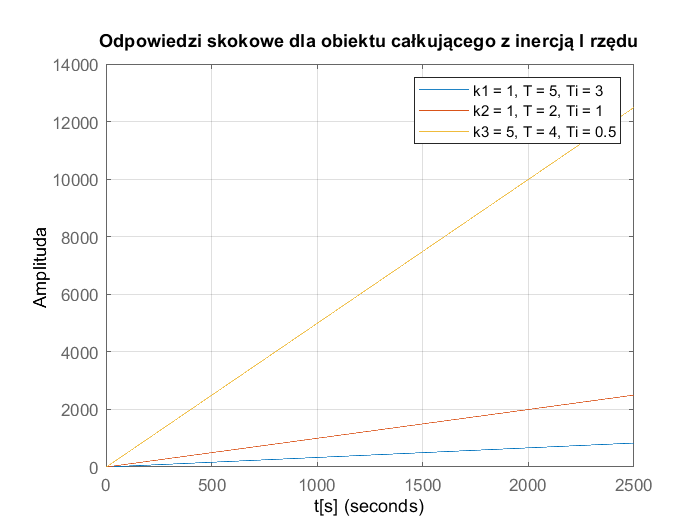

% obiekt całkujący z inercją I rzędu
figure
hold on
step([0, 0, 1], [15, 3, 0]); 
step([0, 0, 1], [2, 1, 0]); 
step([0, 0, 5], [2, 1, 0]); 
title("Odpowiedzi skokowe dla obiektu całkującego z inercją I rzędu")
xlabel("t[s]")
ylabel("Amplituda")
legend(["k1 = 1, T = 5, Ti = 3", "k2 = 1, T = 2, Ti = 1", "k3 = 5, T = 4, Ti = 0.5"])
grid on

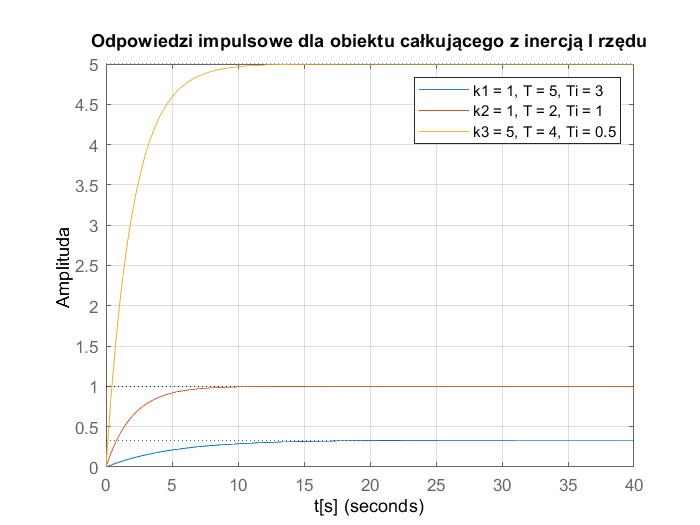


figure
hold on
impulse([0, 0, 1], [15, 3, 0]); 
impulse([0, 0, 1], [2, 1, 0]); 
impulse([0, 0, 5], [2, 1, 0]); 
title("Odpowiedzi impulsowe dla obiektu całkującego z inercją I rzędu")
xlabel("t[s]")
ylabel("Amplituda")
legend(["k1 = 1, T = 5, Ti = 3", "k2 = 1, T = 2, Ti = 1", "k3 = 5, T = 4, Ti = 0.5"])
grid on

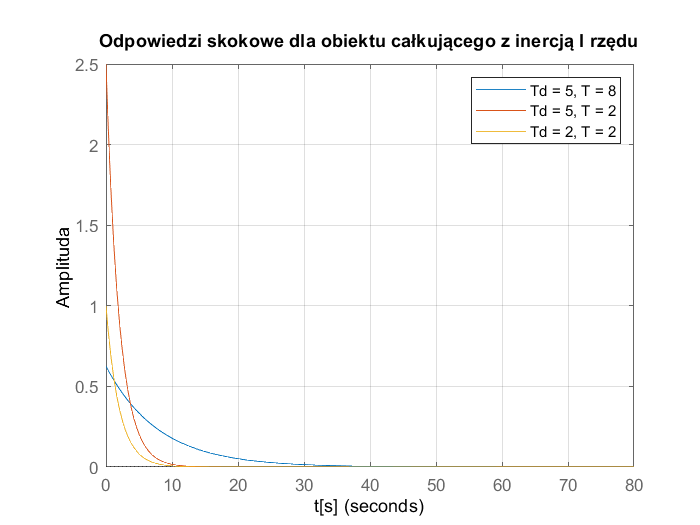

% obiekt różniczkujący rzeczywisty
figure
hold on
step([5, 0], [8, 1]); 
step([5, 0], [2, 1]); 
step([2, 0], [2, 1]); 
title("Odpowiedzi skokowe dla obiektu różniczkującego rzeczywistego")
xlabel("t[s]")
ylabel("Amplituda")
legend(["Td = 5, T = 8", "Td = 5, T = 2", "Td = 2, T = 2"])
grid on

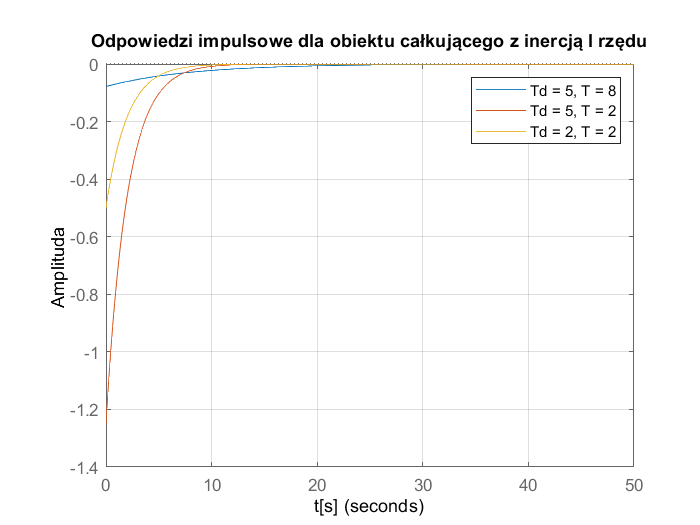


figure
hold on
impulse([5, 0], [8, 1]); 
impulse([5, 0], [2, 1]); 
impulse([2, 0], [2, 1]); 
title("Odpowiedzi impulsowe dla obiektu różniczkującego rzeczywistego")
xlabel("t[s]")
ylabel("Amplituda")
legend(["Td = 5, T = 8", "Td = 5, T = 2", "Td = 2, T = 2"])
grid on

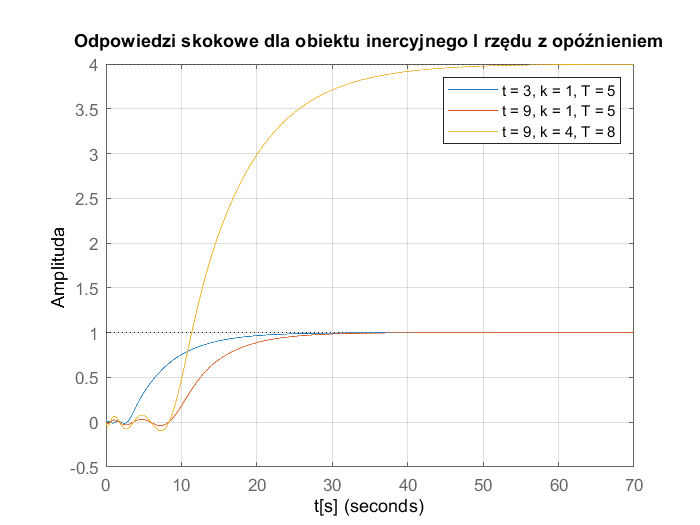

% obiekt inercyjny I rzędu z opóźnieniem
[del_l, del_m] = pade(3, 5);
licz = [0, 1]; 
mian = [5, 1];
[licz_d1, mian_d1] = series(del_l, del_m, licz, mian);
[del_l, del_m] = pade(9, 5);
licz = [0, 1]; 
mian = [5, 1];
[licz_d2, mian_d2] = series(del_l, del_m, licz, mian);
[del_l, del_m] = pade(9, 5);
licz = [0, 4]; 
mian = [8, 1];
[licz_d3, mian_d3] = series(del_l, del_m, licz, mian);
figure
hold on
step(licz_d1, mian_d1)
step(licz_d2, mian_d2)
step(licz_d3, mian_d3)
title("Odpowiedzi skokowe dla obiektu inercyjnego I rzędu z opóźnieniem")
xlabel("t[s]")
ylabel("Amplituda")
legend(["t = 3, k = 1, T = 5", "t = 9, k = 1, T = 5", "t = 9, k = 4, T = 8"])
grid on

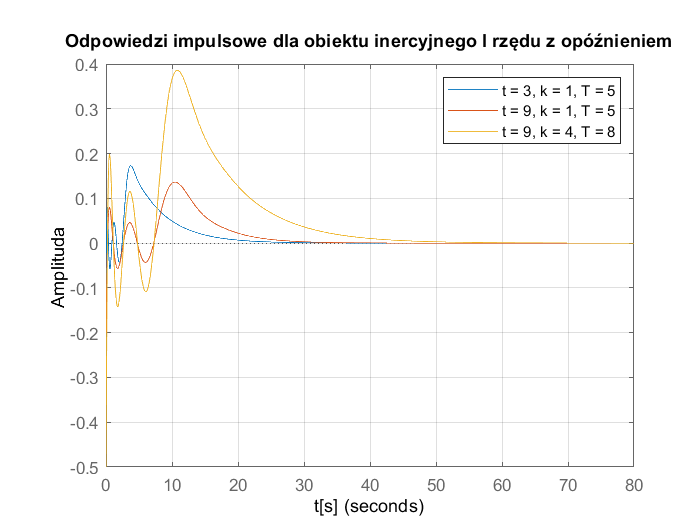


[del_l, del_m] = pade(3, 5);
licz = [0, 1]; 
mian = [5, 1];
[licz_d1, mian_d1] = series(del_l, del_m, licz, mian);
[del_l, del_m] = pade(9, 5);
licz = [0, 1]; 
mian = [5, 1];
[licz_d2, mian_d2] = series(del_l, del_m, licz, mian);
[del_l, del_m] = pade(9, 5);
licz = [0, 4]; 
mian = [8, 1];
[licz_d3, mian_d3] = series(del_l, del_m, licz, mian);
figure
hold on
impulse(licz_d1, mian_d1)
impulse(licz_d2, mian_d2)
impulse(licz_d3, mian_d3)
title("Odpowiedzi impulsowe dla obiektu inercyjnego I rzędu z opóźnieniem")
xlabel("t[s]")
ylabel("Amplituda")
legend(["t = 3, k = 1, T = 5", "t = 9, k = 1, T = 5", "t = 9, k = 4, T = 8"])
grid on